# Expand Example 3.10:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Find the EFS coefficients of the rectified sinusoidal signal shown below, and compute a finite-harmonic approximation to it.

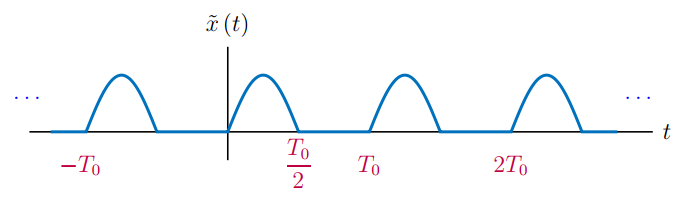

The EFS coefficients are (see Example 3.10)


$$c_{k}=\left\{
\begin{array}{c l}
0\;, & k\;\textrm{odd and}\;k\ne\mp 1 \\
-j/4\;, & k=1 \\
j/4\;, & k=-1 \\
\frac{-1}{\pi\left(k^{2}-1\right)}\;, & k\;\textrm{even}
\end{array}
\right.
$$


Finite-harmonic approximation


$$\hat{x}(t)=\sum_{k=-M}^{M} c_{k}\,e^{jk\omega_{0}t}$$


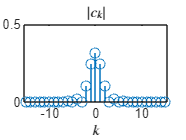

M =      5; % Number of harmonics used in reconstruction
%
t = [-0.25:0.005:2.25];  % Vector of time instants
xp = @(t) sin(2*pi*t).*(t<=0.5);  % Anonymous function 
x = xp(mod(t,1));                 % Periodic extension
% Compute the EFS coefficients for k=-15,...,15
k = [-20:20];
ck = zeros(size(k));
for i=1:2:length(k)  % Coefficients for even k
  kk = k(i);
  ck(i) = -1/pi/(kk*kk-1);
end;
ck(20) = j*0.25;     % This is c(-1)
ck(22) = -j*0.25;    % This is c(+1)
% Graph the magnitude and phase of the line spectrum.
stem(k,abs(ck));
axis([-15.5,15.5,0,0.5]);
set(0,'defaultTextInterpreter','latex');
xlabel('$k$');
title('$|c_{k}|$');

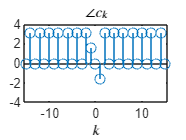

stem(k,angle(ck));
axis([-15.5,15.5,-4,4]);
xlabel('$k$');
title('$\angle c_{k}$');

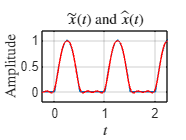

% Compute and graph the finite-harmonic approximation
omg0 = 2*pi;
xhat = zeros(size(t));
for kk=-M:M,
  xhat = xhat+ck(kk+21)*exp(j*kk*omg0*t);
end;  
xhat = real(xhat);  % In case there is residual imaginary part
plot(t,x,t,xhat,'r'); grid;
axis([-0.25,2.25,-0.2,1.2]);
xlabel('$t$');
ylabel('Amplitude');
title('$\tilde{x}(t)$ and $\hat{x}(t)$');

set(0,'defaultTextInterpreter','tex');